# Sample 3-3

## 平滑化／先鋭化処理

勾配フィルタ 

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image smoothing/sharpening

Gradient filter

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### サンプル画像の準備

(Preparation of sample image)

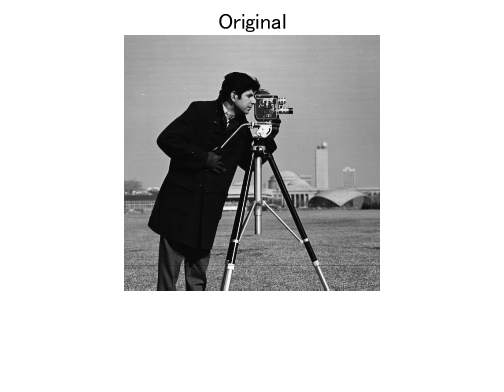

close
% Reading original image
I = im2double(imread('cameraman.tif'));
figure(1)
imshow(I)
title('Original')

### フィルタカーネルの選択

(Selecting the filter kernel)

- Sobel

- Prewitt

ftype = 'Sobel';

### 勾配フィルタ

(Gradient filter)


$$\nabla x=\left(\begin{array}{c}\frac{\partial x}{\partial p_\mathrm{v}}\\
\frac{\partial x}{\partial p_\mathrm{h}}
\end{array}\right)$$


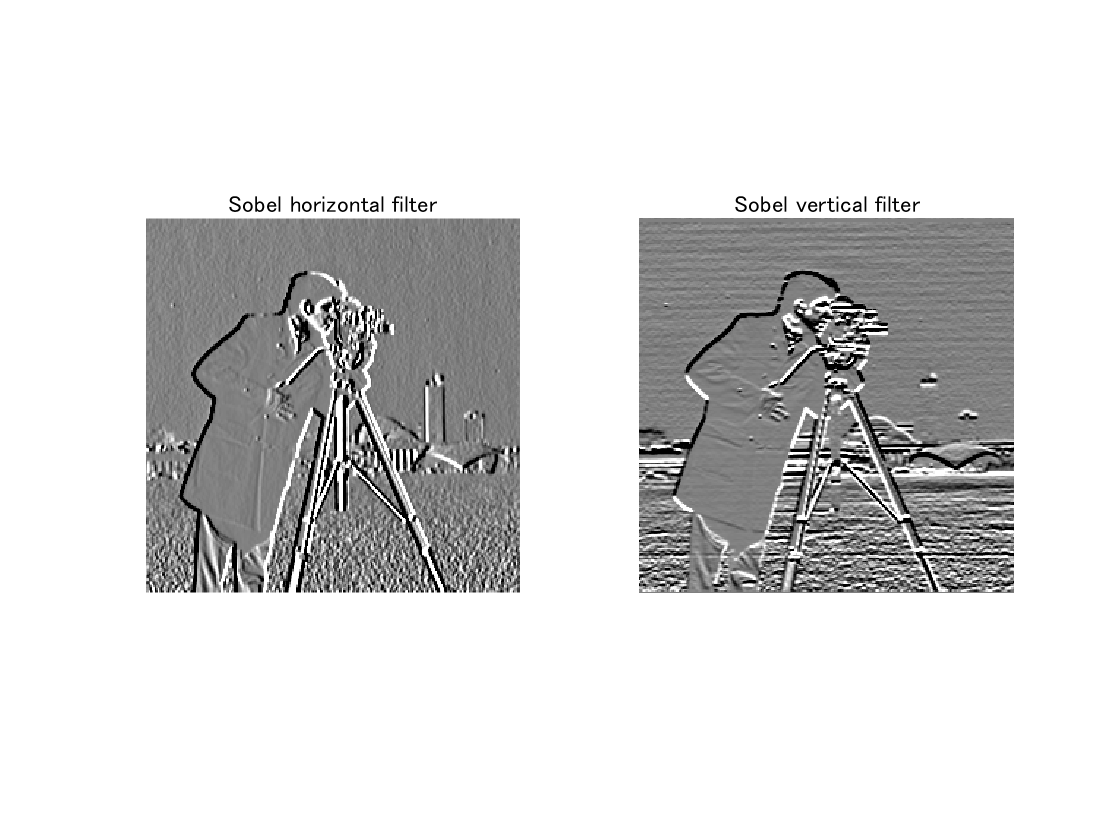

% Gradient flter
[Gh,Gv] = imgradientxy(I,ftype);

% Show result in the horizontal direction
figure(2)
subplot(1,2,1)
imshow(Gh+.5)
title([ftype ' horizontal filter'])
% Show result in the vertical direction
subplot(1,2,2)
imshow(Gv+.5)
title([ftype ' vertical filter'])

### 勾配の可視化

(Visualization of gradient)


$$\nabla x=\left(\begin{array}{c}\frac{\partial x}{\partial p_\mathrm{v}}\\
\frac{\partial x}{\partial p_\mathrm{h}}
\end{array}\right)$$


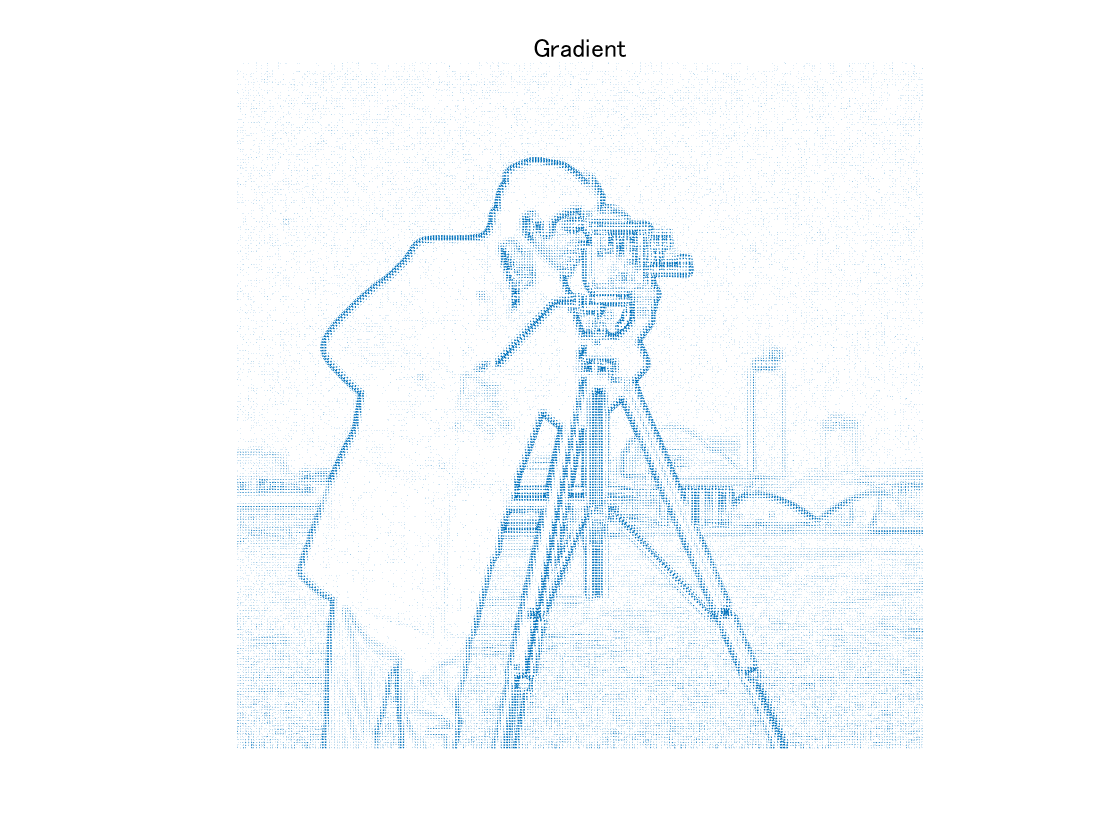

% Gradient
figure(3)
quiver(Gh,Gv)
title('Gradient')
axis equal
axis off
axis ij

### 勾配の大きさと方向

(Magnitude and direction of gradient)


$$\left|\nabla x\right|=\sqrt{\left(\frac{\partial x}{\partial p_\mathrm{v}}\right)^2+\left(\frac{\partial x}{\partial p_\mathrm{h}}\right)^2}$$



$$\angle\nabla x=\tan^{-1}\frac{\left(\frac{\partial x}{\partial p_\mathrm{v}}\right)}{\left(\frac{\partial x}{\partial p_\mathrm{h}}\right)}$$


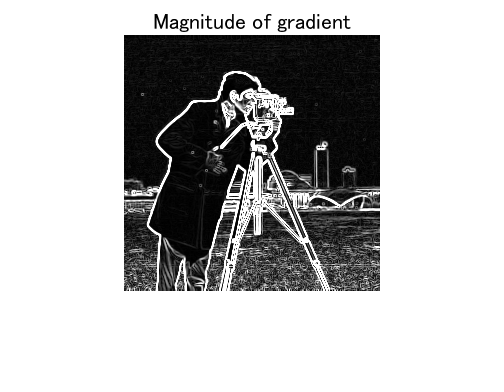

% Gradient filter
[Gm,Gd] = imgradient(I,ftype);

% Show result of magnitude
figure(4)
imshow(Gm)
title('Magnitude of gradient')

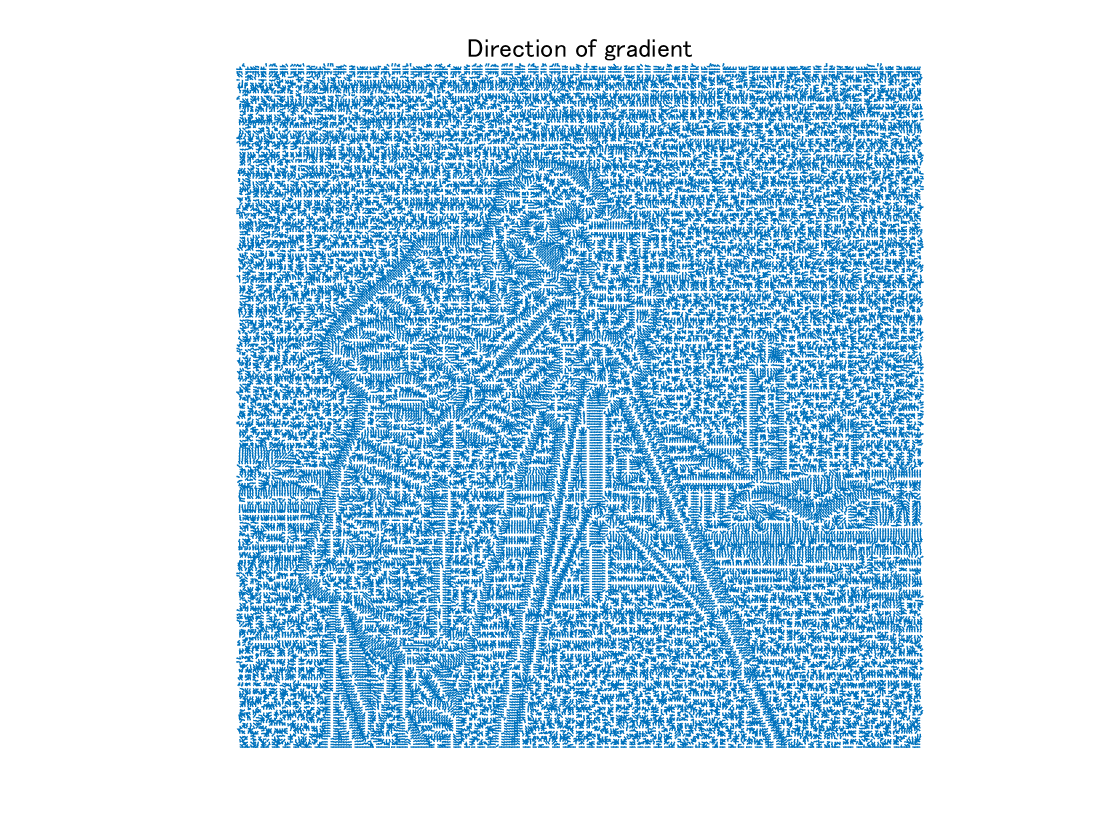

% Show result of direction
figure(5)
quiver(cosd(Gd),-sind(Gd))
title('Direction of gradient')
axis equal
axis off
axis ij

### エッジ検出

(Edge detection)

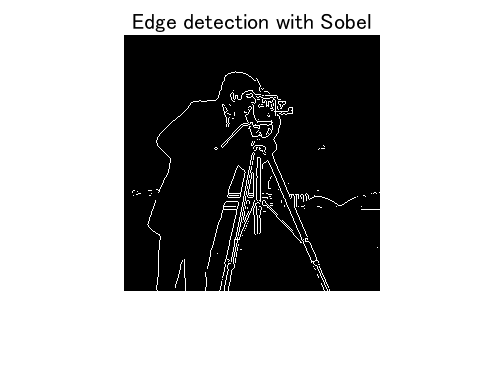

% Edge detection
E = edge(I,ftype);

% Show result 
figure(6)
imshow(E)
title(['Edge detection with ' ftype])

© Copyright, Shogo MURAMATSU, All rights reserved.